# **Chapter 16 Mini Quiz Q1 (MiniQuiz-Lec11)**

**1) Let's assume y = 0.5e^(0.1x) + 2        Let's plot this function from x = 0 to 40**

xx = 0:1:40

xx =      0     1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30    31    32    33    34    35    36    37    38    39    40


yy = 0.5*exp(0.1*xx) + 2

yy =     2.5000    2.5526    2.6107    2.6749    2.7459    2.8244    2.9111    3.0069    3.1128    3.2298    3.3591    3.5021    3.6601    3.8346    4.0276    4.2408    4.4765    4.7370    5.0248    5.3429    5.6945    6.0831    6.5125    6.9871    7.5116    8.0912    8.7319    9.4399   10.2223   11.0871   12.0428   13.0990   14.2663   15.5563   16.9821   18.5577   20.2991   22.2237   24.3506   26.7012   29.2991


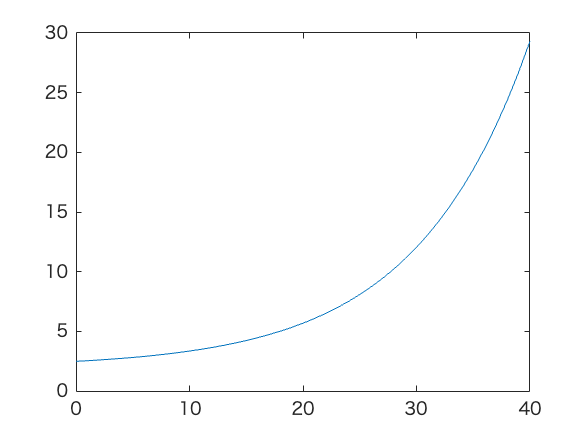

plot(xx, yy, '-')

**2) If we know this function and we want to find out what is y when x = 22?**

xtest = 22

xtest = 22

y_true = 0.5*exp(0.1*xtest) + 2

y_true = 6.5125

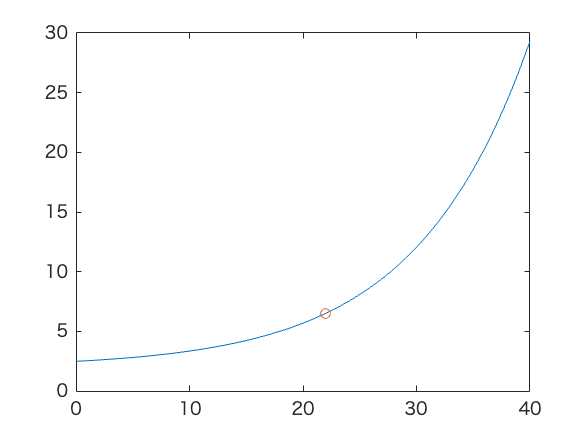

plot(xx, yy, '-', xtest, y_true, 'o')

**3) Now let's assume that we don't know this function, but we know only some points on this function. **

**For example, if we only know 2 points with equal interval between 0 and 40, then we can use ****linear interpolation**** to predict the y value when x = 22**

x = linspace(0, 40, 2);
y = 0.5*exp(0.1*x) + 2;
p1 = polyfit(x, y, 1);

xx = 0:1:40;
yy1 = polyval(p1, xx);

plot(xx, yy, '-', xtest, y_true, 'o') % true value
hold on
plot(xx, yy1, 'm-', x, y, 'bs') % sampled points
hold on

ypred1 = polyval(p1, xtest)

ypred1 = 17.2395

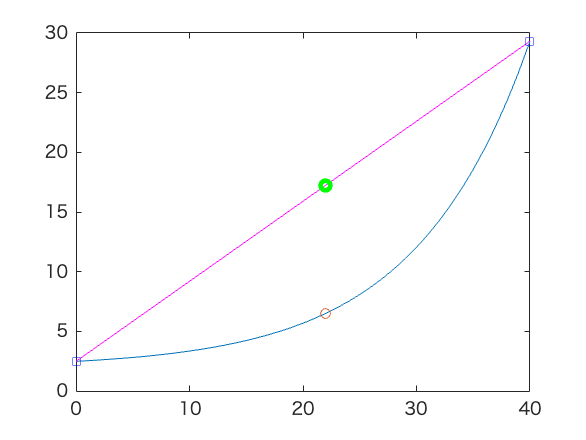

plot(xtest, ypred1, 'go', 'LineWidth', 3)
hold off

**4) Now assume that we only know 3 points with equal interval between 0 and 40, then we can use ****quadratic interpolation**** to predict the y value when x = 22**

x = linspace(0, 40, 3);
y = 0.5*exp(0.1*x) + 2;
p2 = polyfit(x, y, 2);

xx = 0:1:40;
yy2 = polyval(p2, xx)

yy2 =     2.5000    2.1750    1.9010    1.6780    1.5061    1.3852    1.3153    1.2964    1.3286    1.4118    1.5460    1.7313    1.9675    2.2548    2.5931    2.9825    3.4228    3.9142    4.4566    5.0501    5.6945    6.3900    7.1365    7.9341    8.7826    9.6822   10.6328   11.6345   12.6871   13.7908   14.9455   16.1513   17.4081   18.7158   20.0747   21.4845   22.9454   24.4573   26.0202   27.6341   29.2991


nyy2 =     2.5000    2.1750    1.9010    1.6780    1.5061    1.3852    1.3153    1.2964    1.3286    1.4118    1.5460    1.7313    1.9675    2.2548    2.5931    2.9825    3.4228    3.9142    4.4566    5.0501    5.6945    6.3900    7.1365    7.9341    8.7826    9.6822   10.6328   11.6345   12.6871   13.7908   14.9455   16.1513   17.4081   18.7158   20.0747   21.4845   22.9454   24.4573   26.0202   27.6341   29.2991



plot(xx, yy, '-', xtest, y_true, 'o')
hold on
plot(xx, yy2, 'm-', x, y, 'bs')
hold on
ypred2 = polyval(p2, xtest)

ypred2 = 7.1365

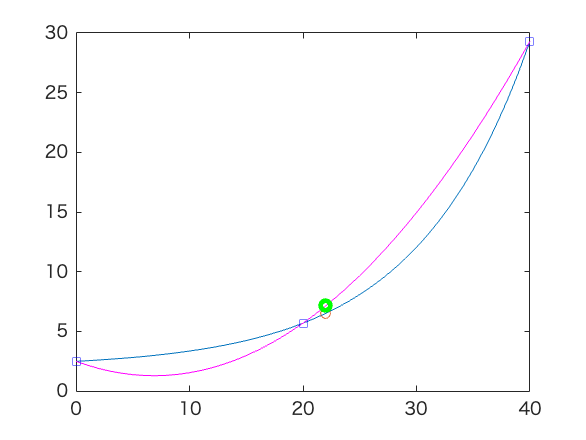

plot(xtest, ypred2, 'go', 'LineWidth', 3)
hold off

**5) Now assume that we only know 4 points with equal interval between 0 and 40, then we can use ****cubic interpolation**** to predict the y value when x = 22**

x = linspace(0, 40, 4);
y = 0.5*exp(0.1*x) + 2;
p3 = polyfit(x, y, 3);

xx = 0:1:40;
yy3 = polyval(p3, xx);

plot(xx, yy, '-', xtest, y_true, 'o')
hold on
plot(xx, yy3, 'm-', x, y, 'bs')
hold on
ypred3 = polyval(p3, xtest)

ypred3 = 6.2153

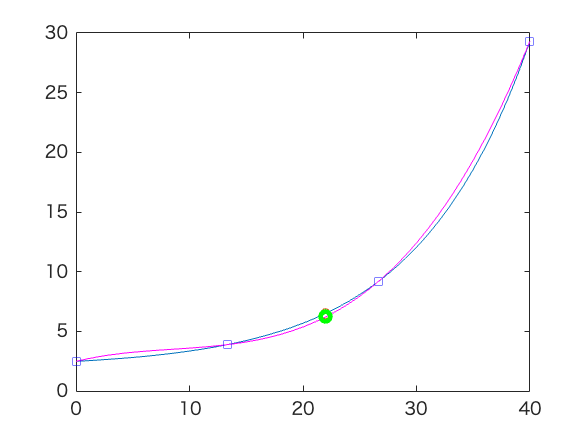

plot(xtest, ypred3, 'go', 'LineWidth', 3)
hold off